## Example Finding Local Maxima and Minima By Trail and Error

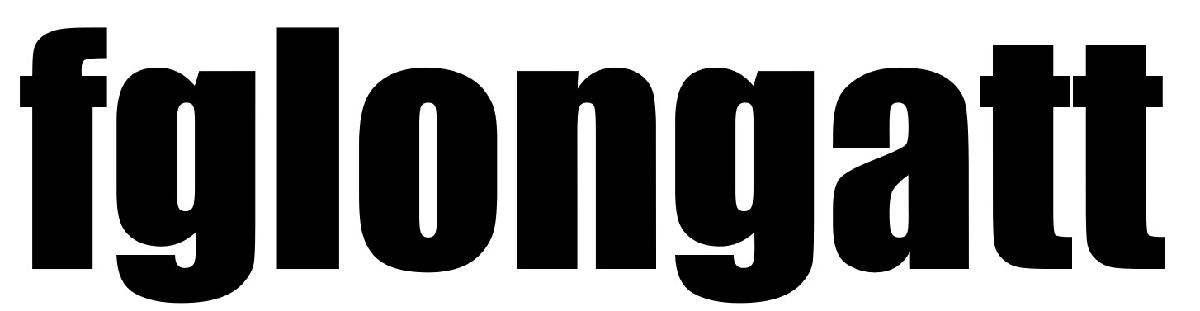  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

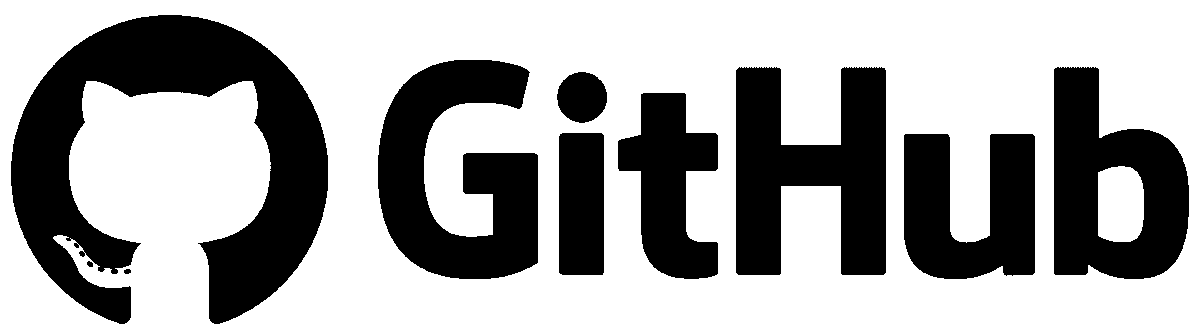 [https://github.com/fglongatt](https://github.com/fglongatt) 

Consider the following *polynomial* function $f\left(x\right)$:


$$f\left(x\right)=e^{-x} \sin \left(\frac{\pi }{2}x\right)$$
 

Find the local *maxima* and *minima *considering $x\in \left\lbrack 0,20\right\rbrack$

clear
clc
N = 100;    % N: Number of points discrete interval

Defining a segment to assess the max/min $x\in \left\lbrack x_{\min } ,x_{\max } \right\rbrack$ and discretising it:

$x_i =x_{\min } +i\left(\frac{x_{\max } -x_{\min } }{N}\right)$ where $i=1,2,\ldotp \ldotp \ldotp ,N$

xmin = 0    % xmin: Min limit of the searching interval

xmin = 0

xmax = 20   % xmax: Min limit of the searching interval

xmax = 20

x = [xmin:1/N:xmax];   

Defining the function $f\left(x\right)$:


$$f\left(x\right)=e^{-x} \sin \left(\frac{\pi }{2}x\right)$$
 

f = exp(-x).*sin(pi./2.*x);  

Searching max/min using pure logic:

**NOTE:** This is a very specific method that can fail in other cases.

fmax = -9999

fmax = -9999

fmin = 9999

fmin = 9999

j = 0; j = j  + 1;
k = 0; k = k + 1;
for(i=2:(xmax-xmin)*N)
   if f(i) >= fmax
       fmax = f(i);
   else
       fMAX(j) = fmax;
   end
   if f(i) <= fmin
       fmin = f(i);
   else
       fMIN(k) = fmin;
   end
end
fprintf(' Global Maximum, x = %4.4f',fMAX )

 Global Maximum, x = 0.4452

fprintf(' Global Minimum, x = %4.4f',fMIN )

 Global Minimum, x = -0.0603

Plotting the function $f\left(x\right)$:

plot(x,f,'-r','LineWidth',2);
xlabel('$x$','Interpreter','latex')
ylabel('$f(x)$','Interpreter','latex')
title_latex = ['$f(x) = e^x\sin(\frac{x\pi}{2})$'];
title(title_latex,'Interpreter','latex')
set(gca,"fontsize",12);

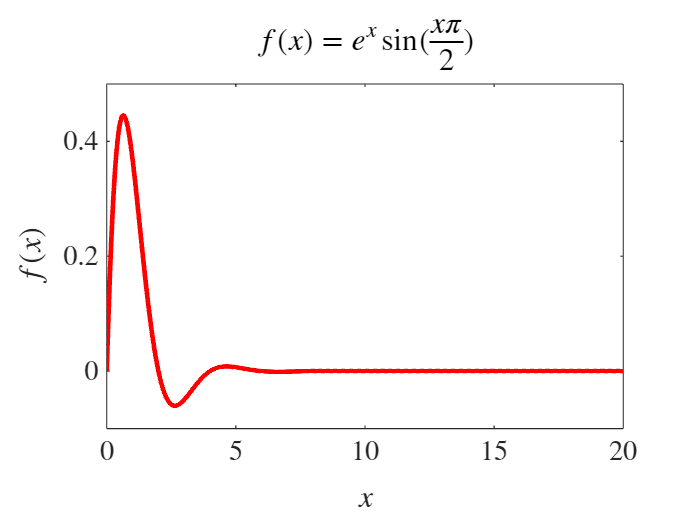

set(gca,'TickLabelInterpreter','latex')